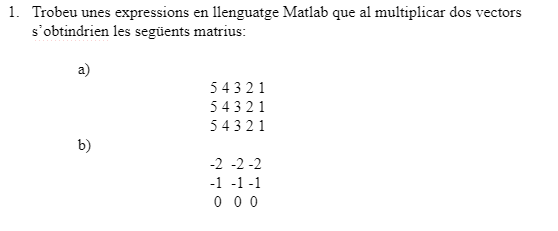

% a)
x = [5 4 3 2 1]

x =      5     4     3     2     1


y = ones(3,1)

y =      1
     1
     1


result = y*x

result =      5     4     3     2     1
     5     4     3     2     1
     5     4     3     2     1


% b)
x = [-2 -1 0]'

x =     -2
    -1
     0


y = ones(3,1)'

y =      1     1     1


result = x*y

result =     -2    -2    -2
    -1    -1    -1
     0     0     0


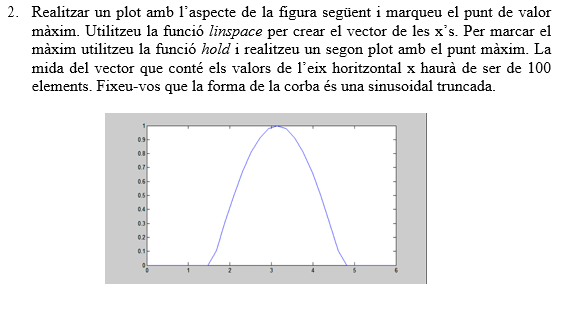

x = linspace(0,6,100)

x =          0    0.0606    0.1212    0.1818    0.2424    0.3030    0.3636    0.4242    0.4848    0.5455    0.6061    0.6667    0.7273    0.7879    0.8485    0.9091    0.9697    1.0303    1.0909    1.1515    1.2121    1.2727    1.3333    1.3939    1.4545    1.5152    1.5758    1.6364    1.6970    1.7576    1.8182    1.8788    1.9394    2.0000    2.0606    2.1212    2.1818    2.2424    2.3030    2.3636    2.4242    2.4848    2.5455    2.6061    2.6667    2.7273    2.7879    2.8485    2.9091    2.9697


y = sin(x-pi/2)

y =    -1.0000   -0.9982   -0.9927   -0.9835   -0.9708   -0.9544   -0.9346   -0.9114   -0.8847   -0.8549   -0.8219   -0.7859   -0.7470   -0.7054   -0.6611   -0.6145   -0.5655   -0.5146   -0.4617   -0.4071   -0.3510   -0.2937   -0.2352   -0.1759   -0.1160   -0.0556    0.0050    0.0655    0.1258    0.1857    0.2449    0.3031    0.3603    0.4161    0.4705    0.5230    0.5737    0.6223    0.6685    0.7123    0.7536    0.7920    0.8275    0.8600    0.8893    0.9154    0.9381    0.9574    0.9731    0.9853


y(y<0)=0

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0050    0.0655    0.1258    0.1857    0.2449    0.3031    0.3603    0.4161    0.4705    0.5230    0.5737    0.6223    0.6685    0.7123    0.7536    0.7920    0.8275    0.8600    0.8893    0.9154    0.9381    0.9574    0.9731    0.9853


plot(x,y)
hold on

[M,I] = max(y)

M = 1.0000

I = 53

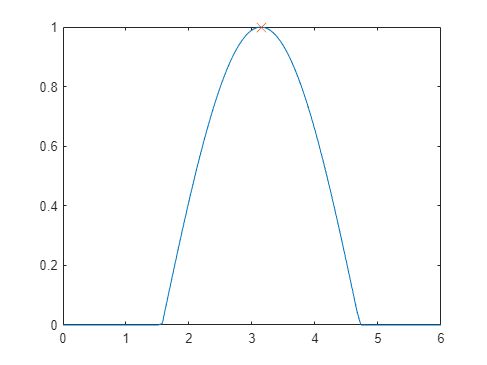


plot(x(I),M,'x','MarkerSize',10);

hold off

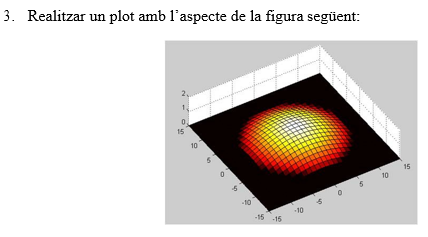

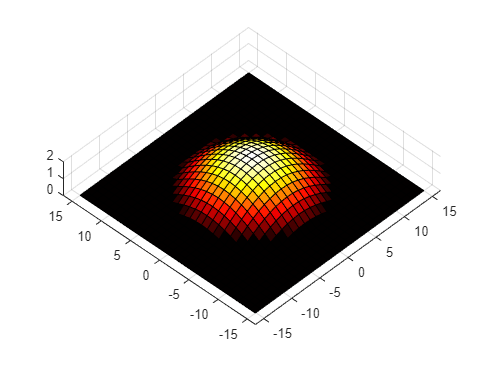

 [x y] = meshgrid(-15:1:15);    
 z = 2 * cos(sqrt(x.^2+y.^2)/(2*pi));
 z(z<0) = 0;
 surf(x,y,z);    
 colormap hot;

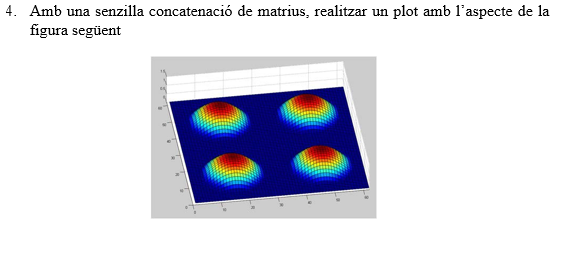

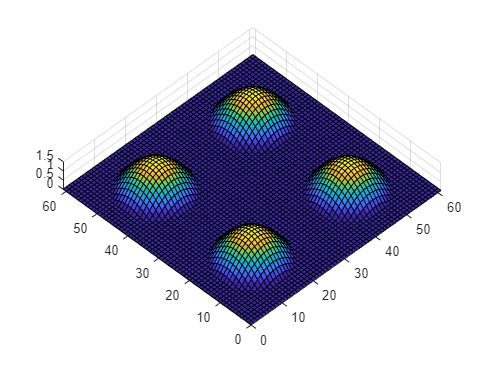

[x y] = meshgrid(-15:1:15);  
z = 2 * cos(sqrt(x.^2+y.^2)/(2*pi));

z = z*1.5/2; %%para que los picos esten en 1.5

z2 = repmat(z, 2, 2);

[x2, y2] = meshgrid(0:1:61);

z2(z2 < 0) = 0;

surf(x2,y2,z2);
colormap default;

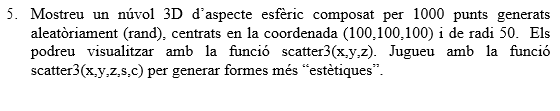

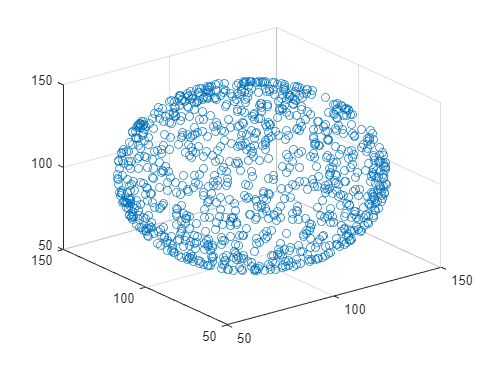

a = 2*pi*rand(1000,1);
radii = 50;
rvals = 2*rand(1000,1)-1;
elevation = asin(rvals);
[x,y,z] = sph2cart(a,elevation,radii);
x = x+100;
y = y+100;
z = z+100;
scatter3(x,y,z)